## Bracketing Methods: Bisection Method

In this livescript, you will learn how to 

- Write a MATLAB program that implements the Bisection method to solve an algebraic nonlinear equation

We'll be considering the problem


$$f(x)=x^{3}-x=0$$


*Equation 1.*

It is always a good idea to plot$f(x)$ to see what it looks like and get an idea where the roots are.  

(a)    Plot $f(x)$ for $-2\leq x \leq 2$ 

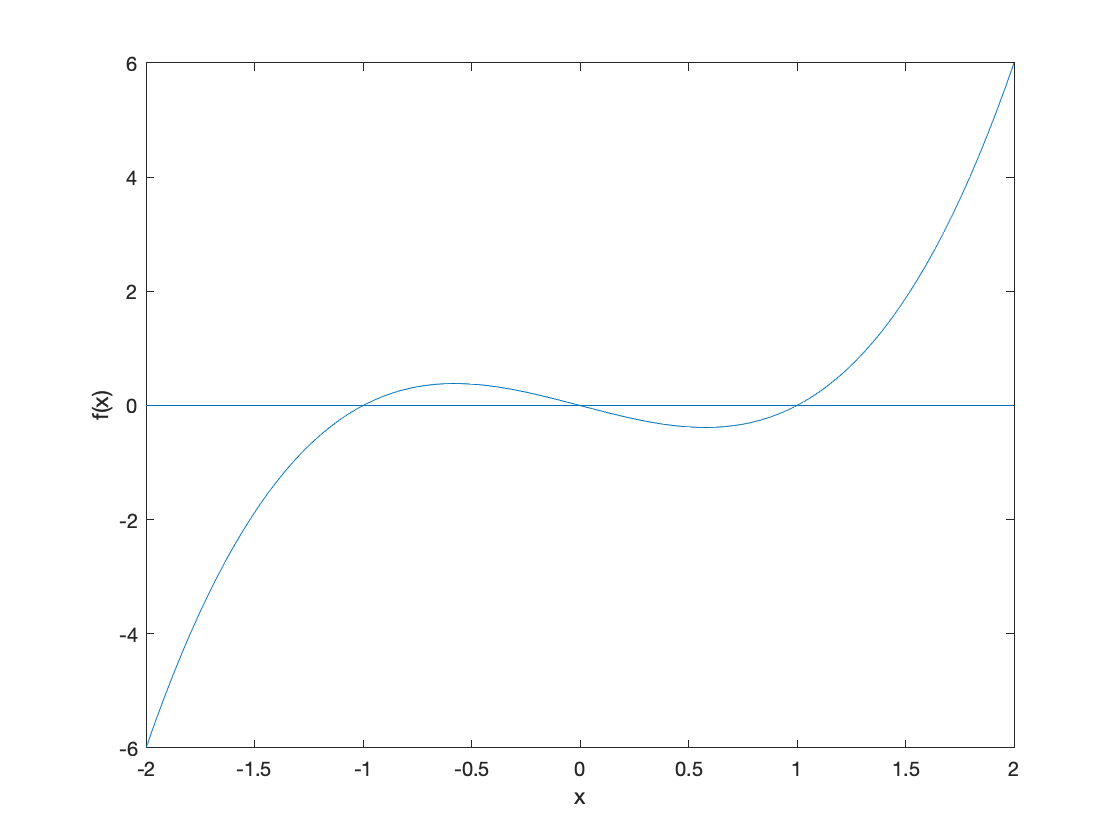

x=linspace(-2,2,100);
fx=x.^3-x;
plot(x,fx);
xlabel('x');
ylabel('f(x)');

%Plot a horizontal line at y=0 so that we can better see where the root is
y=0;
line([-2,2],[y,y])

From the graph generated, you can see that there is one root at $-1$, one at $x=0$ and another one at $x=1$.

(b)    To get an idea of how the bisection method works run the function $\texttt{bisection\_example}$. 

You're going to have to choose lower and upper bounds for the root and then choose whether to move the upper or lower bound to the average value.

You don't have to understand how this function works, as the function is written so that you can interact with it and choose whether $x_{\ell}=x_{r}$ or $x_{u}=x_{r}$ at each step.

xinput = -0.1928

yinput = -0.0131

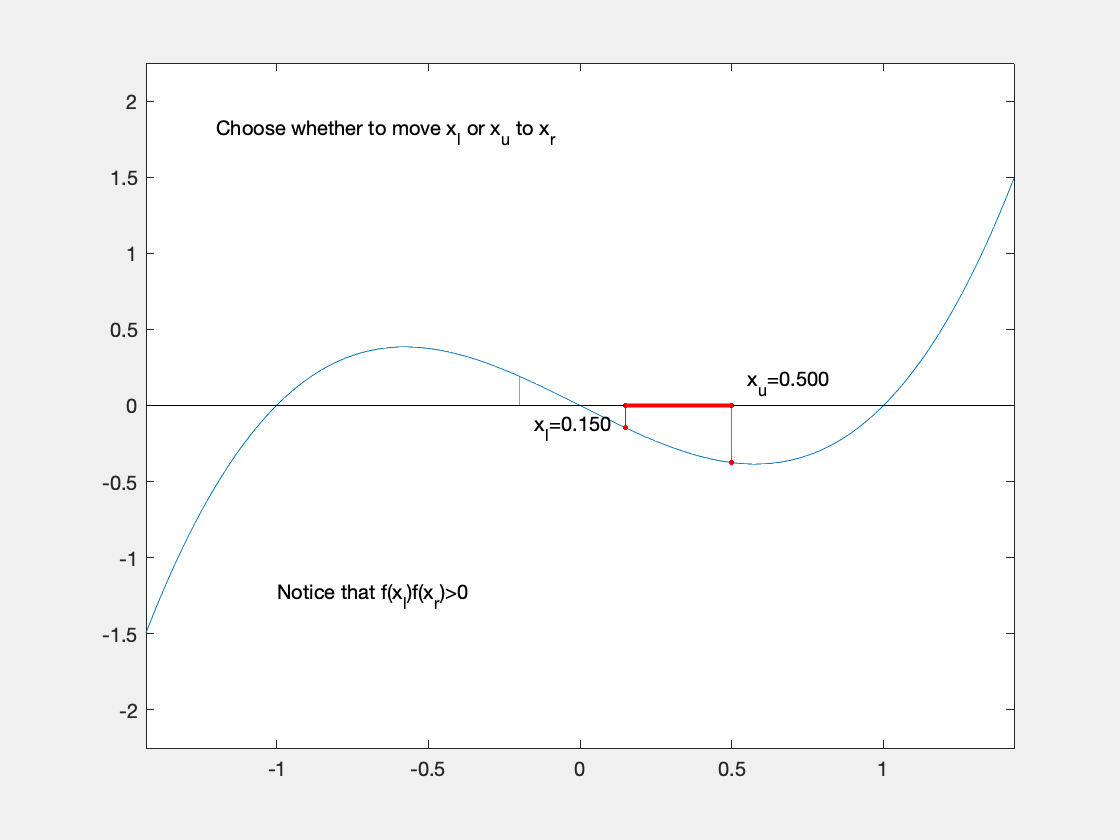

bisection_example

Cutting out all the unnecessary code for interactivity, the Bisection method can be implemented using 

%%%%%%%%%%%%%%%%%%%%%%%%%%%
% bisection_method_solver %
%%%%%%%%%%%%%%%%%%%%%%%%%%%

f=@(x) x.^3-x;

x_l = -2.2; %Initial lower guess of root
x_u = -0.8; %Initial upper guess of root


eps = 1.0e-6; %Accuracy of your answer
maxiter = 50; %maximum number of iterations

x_r=(x_l+x_u)/2

x_r = -1.5000


while abs(f(x_r))>eps
    f_l=f(x_l);
    f_u=f(x_u);
    f_r=f(x_r);
    if f_r*f_l < 0
        x_u= x_r;
    elseif f_r*f_u < 0
        x_l= x_r;
    end
    x_r=(x_l+x_u)/2
end

x_r = -1.1500

x_r = -0.9750

x_r = -1.0625

x_r = -1.0188

x_r = -0.9969

x_r = -1.0078

x_r = -1.0023

x_r = -0.9996

x_r = -1.0010

x_r = -1.0003

x_r = -1.0000

x_r = -1.0001

x_r = -1.0000

x_r = -1.0000

x_r = -1.0000

x_r = -1.0000

x_r = -1.0000

x_r = -1.0000

x_r = -1.0000

x_r = -1.0000

(c)    Change the values of $\texttt{x\_l}$ and $\texttt{x\_u}$ and see if you can make the Bisection method find the different roots of the equation. Try 

-  $\texttt{x\_l}=-1.2$ and $\texttt{x\_u}=1.2$ 

-  $\texttt{x\_l}=-1.2$ and $\texttt{x\_u}=1.3$ 

-  $\texttt{x\_l}=-1.2$ and $\texttt{x\_u}=1.1$ 

What do the values converge to? Can think of why this might be the case?